# **OPC UA Security**

The OPC UA Security product example illustrates how to configure user authentication and encrypted data transfer in the [OPC UA driver](https://www.speedgoat.com/help/slrt/page/io_main/refentry_opcua_landing) blocks for client and server. The Simulink model is almost the same as the [OPC UA Loopback example](https://www.speedgoat.com/help/slrt/page/examples/OPCUA_1Client2Server), except for the security and authentication settings in the [OPC UA Client Connection](https://www.speedgoat.com/help/slrt/page/io_main/refentry_opcua_client_connection) and [OPC UA Server Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_opcua_server_setup) blocks.

In this example, one OPC UA Client communicates with two OPC UA Servers. All three OPC UA stations are in the same system and on the same Ethernet interface. This is achieved by assigning multiple IP addresses to one Ethernet interface. With this setup, the OPC UA Client and Servers are on the same physical Ethernet interface. Both servers provide data that the client can read and write.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with at least one unused Ethernet interface

- "Runtime License File" that includes one OPC UA Client license and two OPC UA Server licenses. Refer to the [Runtime Licensing](https://www.speedgoat.com/help/slrt/page/io_main/refentry_runtime_license) documentation for more information

The OPCUA_Cert.zip package includes the certificate and private key files required by the example. Unzip the file into the same directory which contains the model file.

 
% Unpack the certificates
unzip("OPCUA_Cert");

Certificate verification requires a valid system time. 

 
% Adjust the target time
speedgoat.getTargetTime;

### Wiring of Target Machine

No physical wiring is required.

### Ethernet Configuration of the Client and Servers

Use the **Speedgoat Ethernet Configuration Tool** to assign the **IP address** to one unused Ethernet interface (on-board or IO71x/IO79x) on the target machine. Communication between the client and the server(s) on the unused Ethernet interface is performed over the localhost. No cable is required.

The **IP address** assigned should be 192.168.10.1. The netmask for this local address is 255.255.255.0. This IP is used as the gateway address for the client and server(s) in this example.

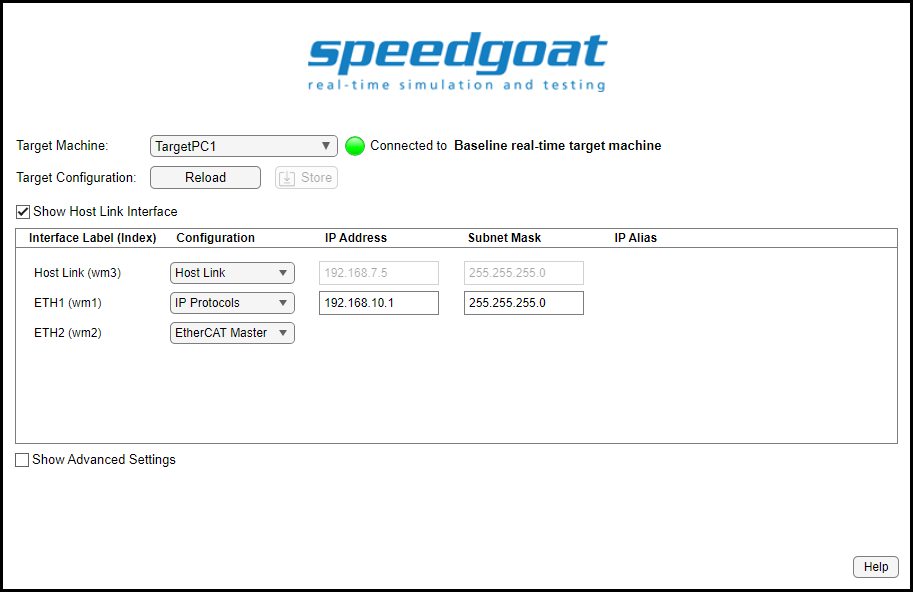

 
% Configure the Ethernet interface for the OPC UA example
speedgoat.configureEthernet; % Open the Speedgoat Ethernet Configuration tool

Add the IP addresses of the client and server(s) to the same Ethernet interface. Adapt the name of the interface according to your target machine configuration.

 
IP_Client_10 = '192.168.10.10';
IP_Server_20 = '192.168.10.20';
IP_Server_21 = '192.168.10.21';

InterfaceName = 'ETH1'; % Ethernet Interface on the target machine used for this example. Adapt this according to your machine.
ipAliasObj = speedgoat.IpAliasConfiguration();
ipAliasObj.add(InterfaceName, {IP_Client_10, IP_Server_20, IP_Server_21});

Check the server Ethernet settings:

ipAliasObj.show();

## Initialize and Open the Simulink Model

 
% Sample time
Ts = 0.001;

% Open Simulink model
modelName = 'sgMdl_OPCUA_Security';
open_system(modelName);

### Model Description

The model sets up the communication for the OPC UA Client and the OPC UA Servers. The **Station ID**, **Connection ID** and **IP address** parameters are aligned to achieve a better understanding of signal flow and how the blocks are related. The first server has **Station ID** **20** and its **IP address** ends with **20**. The client communicates with the server via **Connection ID** **20**. The second server has **Station ID** **21** and its **IP address** ends with **21**. The client communicates with the server via **Connection ID** **21**. The client has **Station ID** **10** and its **IP address** ends with **10**. **Station ID** and **Connection ID** parameters are not related to the OPC UA protocol. Instead, they just serve to link blocks in the Simulink model.

In addition to the endpoint with security policy **None**, both servers provide 2 secure endpoints. The first endpoint is used for message encryption and is different for both servers (Basic128Rsa15 and Basic256Sha256). The matching security policies and modes are selected in the corresponding connection blocks on the client side. The last endpoint in the endpoints' list of both servers determines the security policy for username and password encryption (Aes128_Sha256_RsaOaep in both cases). Signing and encryption with OPC UA requires public X509 certificates and private keys for each participant. The files are included in the example and linked with the respective [Client Connection](https://www.speedgoat.com/help/slrt/page/io_main/refentry_opcua_client_connection) and [Server Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_opcua_server_setup) blocks. The first server has no certificate **Trust List** defined; therefore it accepts all client certificates. The second server refers to a **Trust List** that contains the client's certificate only. This server will only allow connection with the client simulated in the model. Connection attempts by external clients will be rejected. You can use an external client tool to connect to the servers in parallel, view the tree and monitor the signals. The UA Expert is a common tool for that purpose.

As for user authentication, both servers allow the following users to connect:

- User 1 with username "user1" and password "password1"

- User 2 with username "user2" and password "password2"

User authentication is configured with the **Usernames** and **Passwords** parameters of the [Server Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_opcua_server_setup) blocks. 

The first [Client Connection](https://www.speedgoat.com/help/slrt/page/io_main/refentry_opcua_client_connection) block uses the user1 credentials to log in to server 1. The second [Client Connection](https://www.speedgoat.com/help/slrt/page/io_main/refentry_opcua_client_connection) block uses the user2 credentials to log in to server 2.

After connection is done, the data exchange is carried out identically to the [OPC UA Loopback example](https://www.speedgoat.com/help/slrt/page/examples/OPCUA_1Client2Server).

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download the real-time application to the target machine
tg.load(modelName);

% Set the stop time
tg.setStopTime(30);     % seconds

% Prepare the Simulink Data Inspector to plot signals
Simulink.sdi.clearAllSubPlots;
Simulink.sdi.setSubPlotLayout(1,1);
Simulink.sdi.view;

% Start the real-time application
tg.start;

% Select the signals for plotting, set the axis limits and line colors
sdiRunIDs = Simulink.sdi.getAllRunIDs;
sdiLatestRun = Simulink.sdi.Run.getLatest;
sdiSignals = sdiLatestRun.getAllSignals;
for k = 1:8 % Display all signals in the plot
    sdiSignals(k).Checked = 1;
end
pause(1)
Simulink.sdi.setSubplotLimits(1,1,'AllRange',[0,30,-140,140]);

The output is then visible in the Simulink Data Inspector (SDI). You should see the four signals the first server receives from the client and the four signals the client receives from the second server.

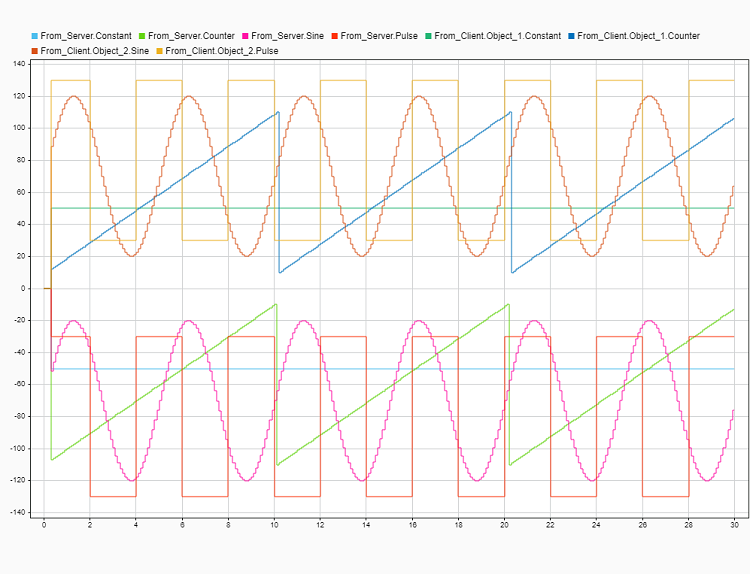

## Restore Target Machine Configuration

To restore the default configuration, you can simply reopen the **Speedgoat Ethernet Configuration Tool** and tick the **Show Advanced Settings** checkbox. Then click the **Restore** button in the bottom right.

This will erase the IPs of every Ethernet interface and set the host link IP to 192.168.7.5 and the netmask to 255.255.255.0.

We recommend restoring the default settings to reduce possible configuration errors.

## Additional References

- [](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_mbtcp_client)[OPC UA Client documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_opcua_client)

- [](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_mbtcp_server)[OPC UA Server documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_opcua_server)